# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Patricia Cuesta Ruiz y Laura Mambrilla Moreno**

**Fecha:**

clc;
clear all;
close all;

# Tema 4. Ejercicio 5 - Texturas

El objetivo de este ejercicio la caracterización de texturas. Para ello, sobre imágenes con texturas diferentes, se obtendrán y compararán los valores de entropía, las matrices de coocurrencia en niveles de gris (GLCM) y estadísticas de las GLCM para diversos valores del vector de *offset*.

 1) Lectura de las imágenes.

% textures from http://www.cb.uu.se/~gustaf/texture/
imagenames = {'texture-stone.png','texture-pattern1.png','texture-linseeds.png', 'texture-canvas.png','texture-pattern2.png','texture-sand.png'};

textureImg = [];
for n = 1:length(imagenames)
    textureImg{n} = imread(imagenames{n});
end

2) **Entropía:** Calcule la entropía de las imágenes de patrones *textureImg* leídas en el paso anterior (usando la función `entropy)`, y ordénelas (usando la función `[MatrizOrdenada,SortedIndex] = sort(Matriz))`, en orden creciente de entropía (de la más baja a la más alta) y muéstrelas según dicho orden. ¿Qué imagen tiene la menor entropía y por qué? Justifique sus conclusiones.

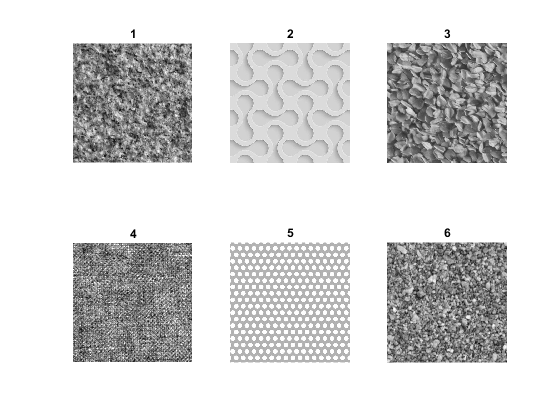

figure;
for n = 1:length(textureImg)
    subplot(2,3,n); imshow(textureImg{n}); title(n);
end

% guardamos las entropías de cada imagen en una lista
im_entropy = [];
for n = 1:length(textureImg)
    im_entropy(n) = entropy(textureImg{n});
end
disp(im_entropy);

    6.8046    4.7936    7.2660    5.9055    4.1983    6.5980



[sorted_matrix, sorted_index] = sort(im_entropy)

sorted_matrix =     4.1983    4.7936    5.9055    6.5980    6.8046    7.2660


sorted_index =      5     2     4     6     1     3


**La entropía mide aleatoriedad de la imagen, es decir, su desorden. Por lo que, la imagen 5 es la que menos entropía presenta ya que en ella hay una gran cantidad de píxeles con las misma intensidades y sigue un mismo patrón por toda ella. En cambio, la imagen 3 es la que más entropía presenta porque hay muchos píxeles con diferentes intensidades.**

3) **GLCM (Matriz de coocurrencia de niveles de gris): **Lea la ayuda de la función `graycomatrix` para entender todos sus parámetros ([https://es.mathworks.com/help/images/ref/graycomatrix.html](https://es.mathworks.com/help/images/ref/graycomatrix.html)). Defina ***offsets*** para las siguientes direcciones (0º, 45º, 90º, 135º) de longitud de lado = 5 (len=5) y utilícelos para crear un conjunto de matrices de coocurrencia (GLCMs), usando la función de `graycomatrix`, para las texturas: '`texture-linseeds.png'` y `'texture-pattern2.png'`. Puede serle útil consultar el código del ejemplo "**Calcular GLM utilizando cuatro desfases diferentes" **de la ayuda de la función `graycomatrix`. 

len = 5;
% P = [row_offset, col_offset]
% P = [0 1] hace referencia un pixel más a la derecha (0º)
%           0         45      90       135
offsets = [0 len; -len len; -len 0; -len -len];

% co-ocurrence matrix of texture-linseeds.png (imagen 3 de la lista textureImg)
[glcms1, texture1] = graycomatrix(textureImg{3}, 'Offset', offsets); 
glcms1(:,:,1)

ans =            0           0           0           0           0           0           0           0
           0        4274        5056        1567         793         291          27           0
           0        5557       41159       15184        7892        3654         808           0
           0        1280       19553       40789       15223        6221        1462           0
           0         531        5614       21249       35185       13049        2114           2
           0         233        2470        5268       16823       29067        6367           1
           0           3         419         548        1853        8054        9141          56
           0           0           0           6           7          10          33           3


glcms1(:,:,2)

ans =            0           0           0           0           0           0           0           0
           0        2443        4470        2253        1740         876         176           0
           0        5258       31618       15463       11508        7825        2109           0
           0        2008       21829       31795       16263        9259        2671           3
           0        1099        8944       23783       26666       13466        3152           1
           0         804        5179        8606       17124       20881        6829           1
           0         168        1530        1808        3831        7561        4928          54
           0           0          13          21          15           6           1           3


glcms1(:,:,3)

ans =            0           0           0           0           0           0           0           0
           0        4359        5328        1328         638         274          37           0
           0        5406       40943       16080        7690        3689         694           0
           0        1393       18878       40349       16359        6303        1260           0
           0         574        5920       19901       34923       14248        2236           0
           0         161        2636        5706       15899       27954        7661           0
           0           6         579        1003        2285        7876        8203          55
           0           0           0          13          12           6          24           7


glcms1(:,:,4)

ans =            0           0           0           0           0           0           0           0
           0        3482        5546        1680         849         266           5           0
           0        5080       37974       18734        8087        3483         435           0
           0        2005       17323       37670       18759        7108        1026           0
           0         969        8258       17537       32646       15662        2078           0
           0         315        3793        6730       14331       26373        8017           0
           0          42         667        1308        2449        6858        8388          46
           0           0           0           0           0          10          39          13


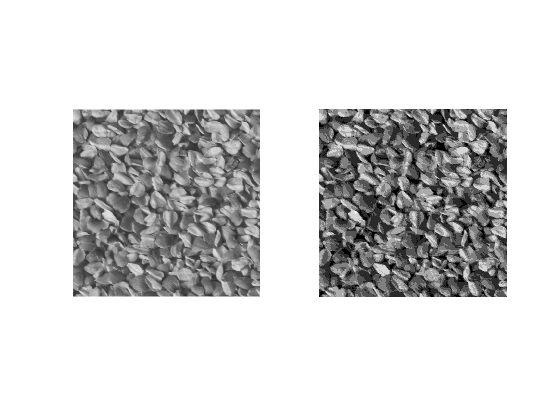

figure;
subplot(1,2,1); imshow(textureImg{3});
subplot(1,2,2); imshow(rescale(texture1));

% co-ocurrence matrix of texture-pattern2.png (imagen 5 de la lista textureImg)
[glcms2, texture2] = graycomatrix(textureImg{5}, 'Offset', offsets); 
glcms2(:,:,1)

ans =            0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           2           0           1
           0           0           0           0           1      160661        7068       29211
           0           0           0           0           0        7136         129        4996
           0           0           0           0           2       29319        4961       85409


glcms2(:,:,2)

ans =            0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           2           0           1
           0           0           0           0           3      144986        6874       43909
           0           0           0           0           0        7481         299        4377
           0           0           0           0           0       42345        4808       70956


glcms2(:,:,3)

ans =            0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           3
           0           0           0           0           3      160666        6567       30333
           0           0           0           0           0        6945         309        4958
           0           0           0           0           0       28798        5263       85051


glcms2(:,:,4)

ans =            0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           1           0           2
           0           0           0           0           3      145007        7073       43866
           0           0           0           0           0        7282         303        4470
           0           0           0           0           0       42347        4708       70979


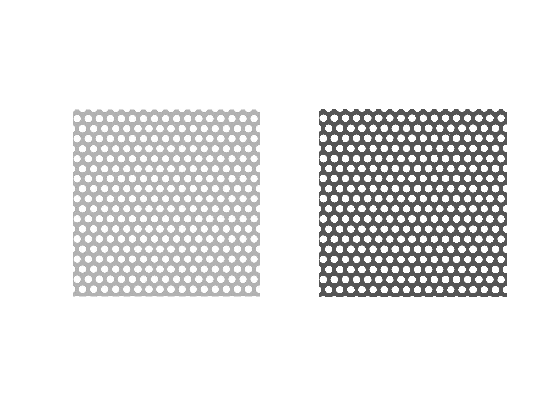

figure;
subplot(1,2,1); imshow(textureImg{5});
subplot(1,2,2); imshow(rescale(texture2));

4) Muestra la imagen de la primera **GLCM** con colores escalados. Para ello puede adaptar el código siguiente:

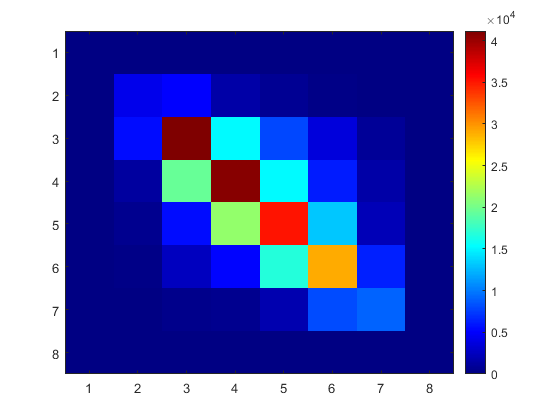

figure;
imagesc(glcms1(:,:,1)); colormap jet; colorbar; % texture-linseeds.png (imagen 3 de la lista textureImg)

**Al ser la imagen con mayor entropía, esto también se ve reflejado en la matriz de co-ocurrencia, donde se puede observar que hay muchos cambios bruscos de intensidades.**

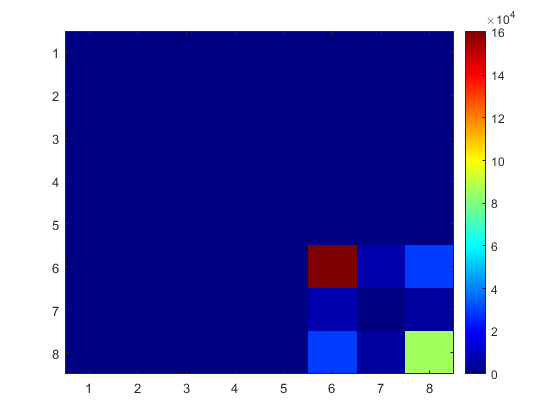

figure;
imagesc(glcms2(:,:,1)); colormap jet; colorbar; % texture-pattern2.png (imagen 5 de la lista textureImg)

**Se puede observar que en su gran mayoría los niveles de intesidad están muy próximos a excepción de una pequeña región donde se aprecia un cambio brusco de intensidades.**

5) **Opcional. **Obtenga estadísticos de la GLCM utilizando la función `graycoprops` para las imágenes `'texture-linseeds.png'` y `'texture-pattern2.png` para varios vectores de offset diferentes. Visualice en función del offset uno de los siguientes estadísticos: `Contrast, Correlation, Energy, Homogeneity`.

%             0    45    90    135
% offsets = [0 5; -5 5; -5 0; -5 -5];

% texture-linseeds.png (imagen 3 de la lista textureImg)
stats1 = graycoprops(glcms1, {'Contrast', 'Correlation'})

stats1 = struct with fields:
       Contrast: [1.1175 1.8643 1.1435 1.2652]
    Correlation: [0.6620 0.4365 0.6543 0.6175]


% texture-pattern2.png (imagen 5 de la lista textureImg)
stats2 = graycoprops(glcms2, {'Contrast', 'Correlation'})

stats2 = struct with fields:
       Contrast: [0.7854 1.1304 0.7914 1.1299]
    Correlation: [0.5673 0.3774 0.5641 0.3777]


%           180    225  270  315
offsets1 = [0 -3; 3 -3; 3 0; 3 3];

% texture-linseeds.png (imagen 3 de la lista textureImg)
[glcms3, texture3] = graycomatrix(textureImg{3}, 'Offset', offsets1);
stats3 = graycoprops(glcms3, {'Contrast', 'Correlation'})

stats3 = struct with fields:
       Contrast: [0.6050 1.1327 0.6478 0.7164]
    Correlation: [0.8170 0.6575 0.8041 0.7834]


% texture-pattern2.png (imagen 5 de la lista textureImg)
[glcms4, texture4] = graycomatrix(textureImg{5}, 'Offset', offsets1);
stats4 = graycoprops(glcms4, {'Contrast', 'Correlation'})

stats4 = struct with fields:
       Contrast: [0.4490 0.6601 0.4515 0.6599]
    Correlation: [0.7527 0.6364 0.7512 0.6365]


%            0    45    90    135
offsets2 = [0 2; -2 2; -2 0; -2 -2];

% texture-linseeds.png (imagen 3 de la lista textureImg)
[glcms5, texture5] = graycomatrix(textureImg{3}, 'Offset', offsets2);
stats5 = graycoprops(glcms5, {'Contrast', 'Correlation'})

stats5 = struct with fields:
       Contrast: [0.3680 0.7112 0.4014 0.4393]
    Correlation: [0.8887 0.7850 0.8786 0.8672]


% texture-pattern2.png (imagen 5 de la lista textureImg)
[glcms6, texture6] = graycomatrix(textureImg{5}, 'Offset', offsets2);
stats6 = graycoprops(glcms6, {'Contrast', 'Correlation'})

stats6 = struct with fields:
       Contrast: [0.2796 0.4209 0.2802 0.4207]
    Correlation: [0.8460 0.7681 0.8456 0.7682]


**Al ir reduciéndose el entorno de vecindad, el valor del contraste de intensidad entre un pixel y su vecino se va reduciendo ya que a medida que los píxeles están más cerca su contraste disminuye al estar más relacionados entre sí, motivo por el cual la correlación aumenta.**